L_t = 2;
L_h = 0.75;
L_i = 1;
v = -1;
delta_t = deg2rad(30)

delta_t = 0.5236

phi = deg2rad(15)

phi = 0.2618

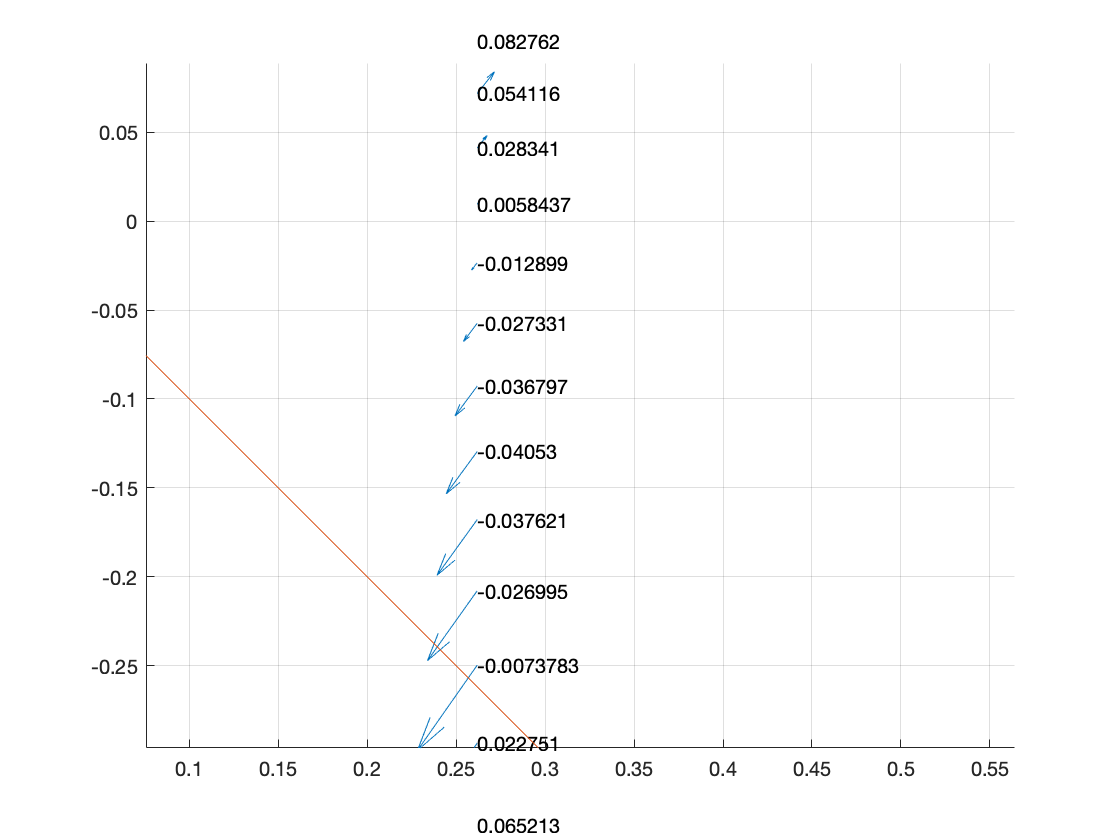

delta_i = deg2rad(linspace(-60,60,100));

k1 = v/L_i*sqrt(1+L_h^2/L_t^2*tan(delta_t)^2);
k2 = atan(L_h/L_t*tan(delta_t)) + phi;
k3 = v/L_t*tan(delta_t);
s2 = sin(k2);
c2 = cos(k2);
t = tan(delta_i);

phi_dot = -k1*(s2+c2*t) - k3;
phi_dot_dot =  -k1*phi_dot.*(c2-s2*t);

e = phi * ones(size(delta_i));
ed = phi_dot;
edd = phi_dot_dot;
s = e + ed;
sd = ed + edd;
ssd = s.*sd;

figure(1), clf, hold on, grid on, axis equal
quiver(e,ed,ed,edd,1);
text(e,ed,"" + ssd)
r = minmax(ed);
plot(-r, r)